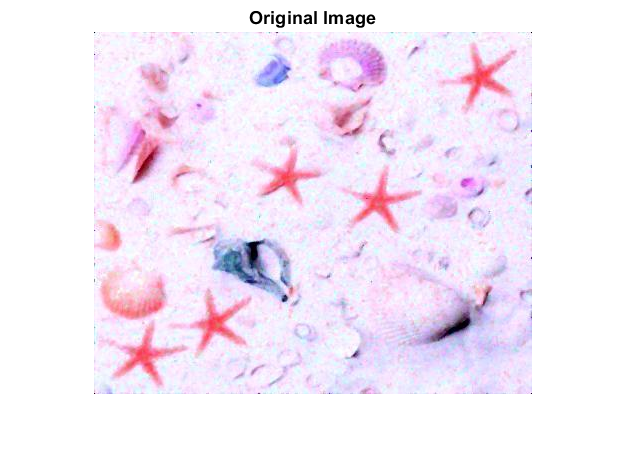

%Load in image
Name = 'starfish_map1.jpg';
Starfish = imread(Name);
imshow(Starfish);
title("Original Image");

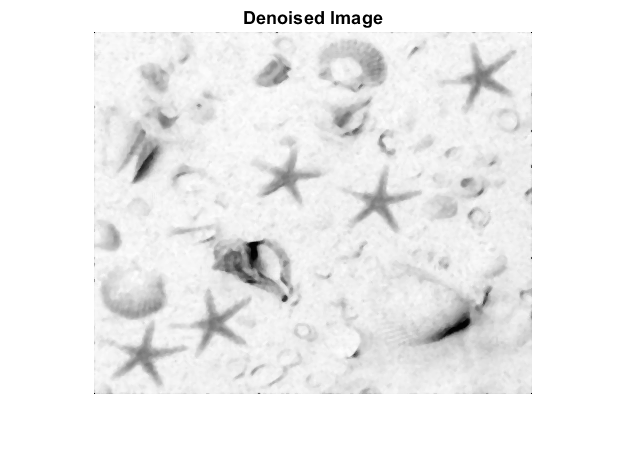


%Denoise and Grayscale
GrayStarfish = rgb2gray(Starfish);
GrayStarfish = medfilt2(GrayStarfish);
imshow(GrayStarfish)
title("Denoised Image");

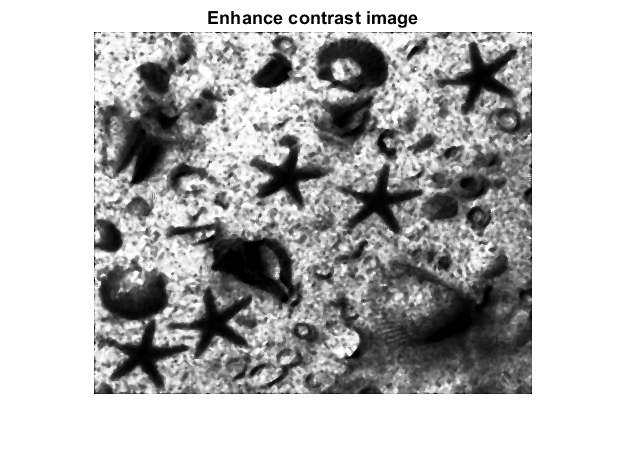


%Enhance constrast and gamma
GrayStarfish = histeq(GrayStarfish);
imshow(GrayStarfish);
title("Enhance contrast image");

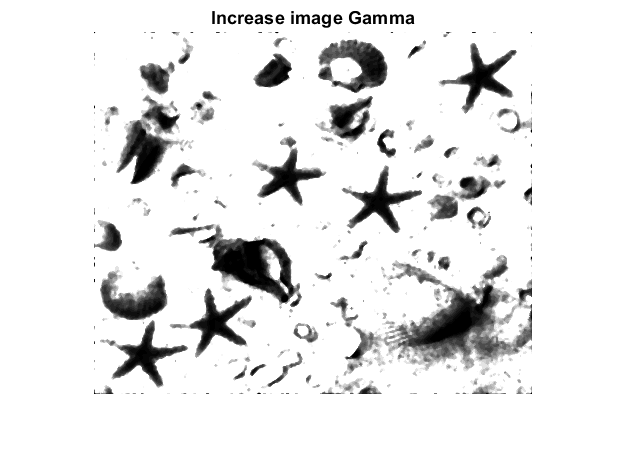

imshow(uint8(double(GrayStarfish) .^1.3));
title("Increase image Gamma");

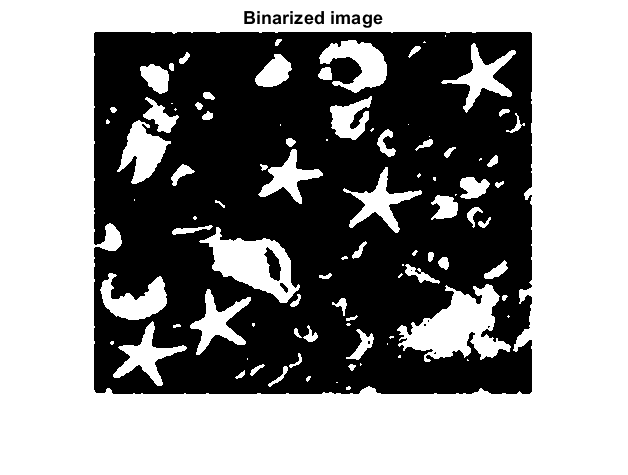

GrayStarfish = uint8(double(GrayStarfish) .^1.3);

% Threshold and binarize the image
thresholdStarfish = graythresh(GrayStarfish);
GrayStarfish = medfilt2(GrayStarfish);
BW1 = imbinarize(GrayStarfish,thresholdStarfish);
BW1 = imcomplement(BW1);
imshow(BW1);
title("Binarized image")

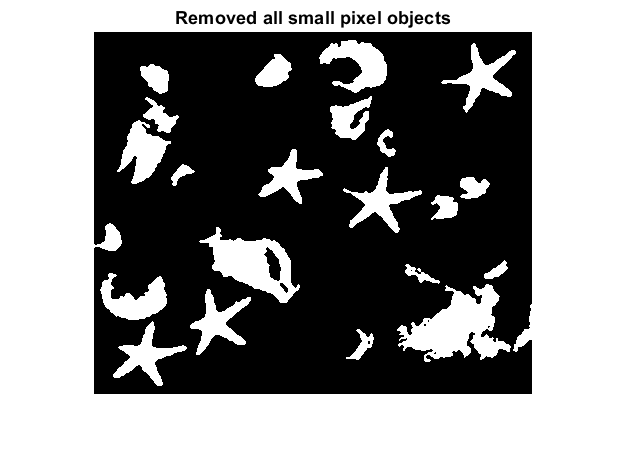


%Remove object smaler then 200 pixel
BW2 = bwareaopen(BW1, 200);
imshow(BW2);
title("Removed all small pixel objects")

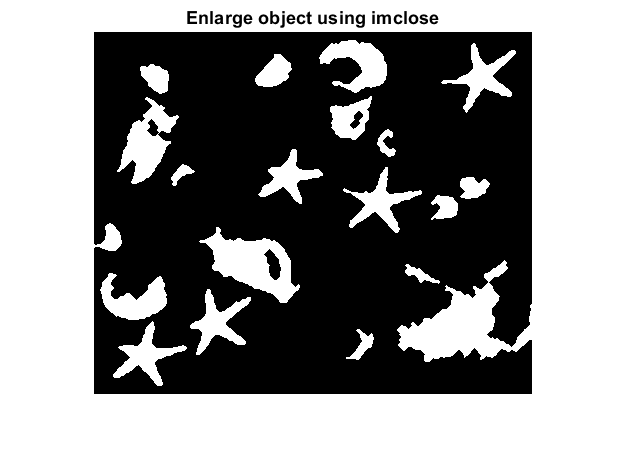


%Enlarge object to fill in small hole within the object
se = strel('diamond',3); 
BW2 = imclose(BW2,se);
imshow(BW2)
title("Enlarge object using imclose");


cc = bwconncomp(BW2)

cc = struct with fields:
    Connectivity: 8
       ImageSize: [362 438]
      NumObjects: 20
    PixelIdxList: {1×20 cell}


info = regionprops(cc,'all');

% Remove any object with hole
labeledImage = bwlabel(BW2);
Hole = [info.EulerNumber]

Hole =      1     1     1     0     1     1     1     0     1     1     1     0     1     1     1     1     1     1     1     1


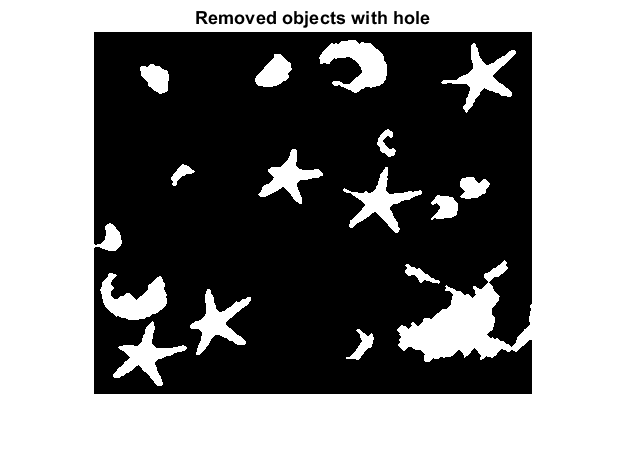

Keep = find(Hole == 1);
BW3 = ismember(labeledImage,Keep) > 0;
imshow(BW3);
title("Removed objects with hole");

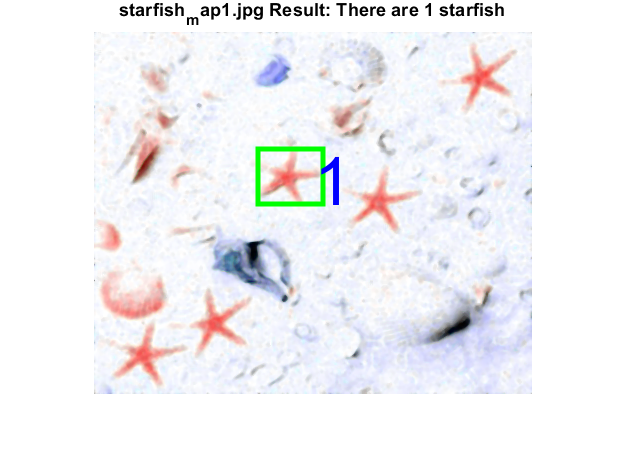


%Get remaining objects status 
stats = regionprops('table',BW3,'BoundingBox',"Centroid","Area","Circularity");
[hei, width] = size(BW3);
Count = 0;
figure;
imshow(StarfishDenoise);
hold on
for k = 1 : height(stats)
    %Calculate the ratio of the remaining objects
    stats.Ratio(k) =  (stats.Area(k,1) / numel(BW3))*100;
    stats.HeightRatio(k) = stats.BoundingBox(k,4)/hei;
    stats.WidthRatio(k) = stats.BoundingBox(k,3)/width;
    %Set bounding box to condition matched objects
    if(stats.Ratio(k) > 0.580  && stats.Ratio(k) < 0.920 && ...
            stats.HeightRatio(k) > 0.124 && stats.WidthRatio(k) > 0.105 && ...
            stats.Circularity(k) < 0.330 && stats.Circularity(k) > 0.160)
        Count = Count + 1;
        BB = stats.BoundingBox(k,:);
        rectangle('Position', [BB(1),BB(2),BB(3),BB(4)],'EdgeColor','g','LineWidth',3) ;
        %H= text(stats.Centroid(k,1) +10, stats.Centroid(k,2),string(k),'color','BLUE','fontsize',44);
        H= text(stats.Centroid(k,1) +25, stats.Centroid(k,2),string(Count),'color','BLUE','fontsize',40);
    end
end
Str = append(Name, " Result: There are ", string(Count), " starfish");
title(Str);
hold off